# %Question1 Smoothing

clc
clear all
%% True track
% Sampling period
T = 0.1;
% Length of time sequence
K = 600;
% Allocate memory
omega = zeros(1,K+1);
% Turn rate
omega(150:450) = -pi/301/T;
% Initial state
x0 = [0 0 20 0 omega(1)]';
% Allocate memory
X = zeros(length(x0),K+1);
X(:,1) = x0;
% Create true track
for i=2:K+1
% Simulate
X(:,i) = coordinatedTurnMotion(X(:,i-1), T);
% Set turn−rate
X(5,i) = omega(i);
end

x_0=[0 0 0 0 0]';N=length(X);
P_0=diag([10^2 10^2 10^2 (5*pi/180)^2 (pi/180)^2]);
s1=[300 -100]';s2=[300 -300]';
sigma_phi1=pi/180;sigma_phi2=pi/180;
R=[sigma_phi1^2 0;0 sigma_phi2^2];
Tau=[0 0 1 0 0;0 0 0 0 1]';
f=@(x,T)coordinatedTurnMotion(x, T);
h=@(x,T) dualBearingMeasurement(x, s1, s2);
Y1 = genNonLinearMeasurementSequence(X, h, R);

sigma_v=0.1;sigma_w=0.1*pi/180;
Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau';
Point=[];
for i=1:600
    [x1, y1] = getPosFromMeasurement(Y1(1,i), Y1(2,i), s1, s2);
    Point=[Point;[x1, y1]];
end
% [xf_tunning, Pf, xp, Pp] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R, 'CKF');
[xs, Ps, xf_tunning, Pf, xp, Pp] = nonLinRTSsmoother(Y1, x_0, P_0, f, T, Q, h, R, @sigmaPoints, 'CKF');

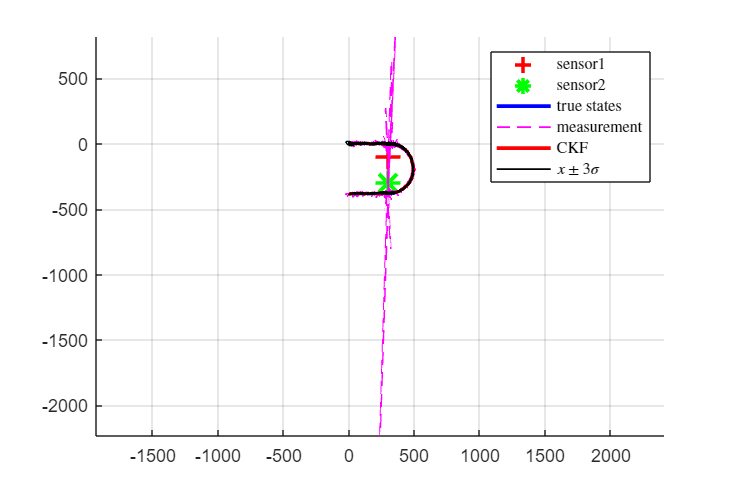

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xf_tunning(1,1:end), xf_tunning(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xf_tunning)
    covEllipse = sigmaEllipse2D(xf_tunning(1:2,i),Pf(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')

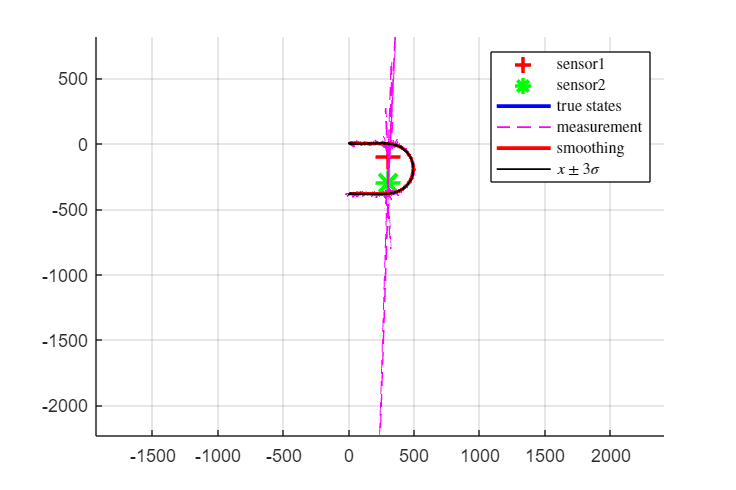

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xs(1,1:end), xs(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xs)
    covEllipse = sigmaEllipse2D(xs(1:2,i),Ps(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','smoothing','$x \pm 3\sigma$','Interpreter','latex')

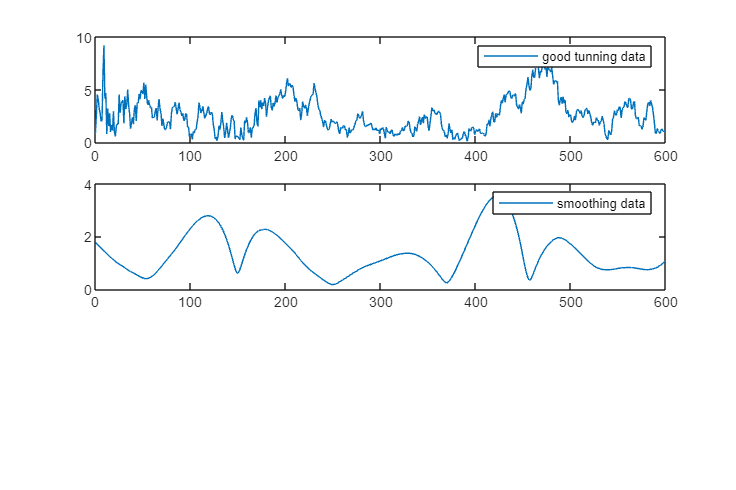

Norm_tunning=vecnorm(X(1:2,2:end)-xf_tunning(1:2,:));
Norm_smoothing=vecnorm(X(1:2,2:end)-xs(1:2,:));
figure('Position',[300 300 600 400]);hold on;
subplot(3,1,1)
plot(0:599,Norm_tunning)
legend("good tunning data")
subplot(3,1,2)
plot(0:599,Norm_smoothing)
legend("smoothing data")

# HA4.1.2 Non-linear RTS smoother

function [xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, T, Q, h, R, sigmaPoints, type)
%NONLINRTSSMOOTHER Filters measurement sequence Y using a 
% non-linear Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence for times 1,...,N
%   x_0         [n x 1] Prior mean for time 0
%   P_0         [n x n] Prior covariance
%   f                   Motion model function handle
%   T                   Sampling time
%   Q           [n x n] Process noise covariance
%   S           [n x N] Sensor position vector sequence
%   h                   Measurement model function handle
%   R           [n x n] Measurement noise covariance
%   sigmaPoints Handle to function that generates sigma points.
%   type        String that specifies type of non-linear filter/smoother
%
%Output:
%   xf          [n x N]     Filtered estimates for times 1,...,N
%   Pf          [n x n x N] Filter error convariance
%   xp          [n x N]     Predicted estimates for times 1,...,N
%   Pp          [n x n x N] Filter error convariance
%   xs          [n x N]     Smoothed estimates for times 1,...,N
%   Ps          [n x n x N] Smoothing error convariance

% your code here!
% We have offered you functions that do the non-linear Kalman prediction and update steps.
% Call the functions using
% [xPred, PPred] = nonLinKFprediction(x_0, P_0, f, T, Q, sigmaPoints, type);
% [xf, Pf] = nonLinKFupdate(xPred, PPred, Y, S, h, R, sigmaPoints, type);
N=size(Y,2);
m = size(Y,1);
n = length(x_0);
xs=zeros(n,N);Ps=zeros(n,n,N);xf=zeros(n,N);Pf=zeros(n,n,N);xp=zeros(n,N);Pp=zeros(n,n,N);
for k=1:N
    [x_predict, P_predict] = nonLinKFprediction(x_0, P_0, f, T, Q, sigmaPoints, type);
    xp(:,k)=x_predict;
    Pp(:,:,k)=P_predict;
    [x_0, P_0] =nonLinKFupdate(x_predict, P_predict, Y(:,k), h, R, sigmaPoints, type);
    xf(:,k)=x_0;
    Pf(:,:,k)=P_0;
end

Ps_kplus1=Pf(:,:,N);
xs_kplus1=xf(:,N);
xs(:,N)=xf(:,N);
Ps(:,:,N)=Pf(:,:,N);
    for k=N-1:-1:1
        [xs_mid, Ps_mid] = nonLinRTSSupdate(xs_kplus1, Ps_kplus1, xf(:,k), Pf(:,:,k), xp(:,k+1),  Pp(:,:,k+1), f, T, sigmaPoints, type);
        xs_kplus1=xs_mid;
        xs(:,k)=xs_mid;
        Ps_kplus1=Ps_mid;
        Ps(:,:,k)=Ps_mid;
    end
end



function [xs, Ps] = nonLinRTSSupdate(xs_kplus1, Ps_kplus1, xf_k, Pf_k, xp_kplus1, Pp_kplus1, f, T, sigmaPoints, type)
    % Your code here! Copy from previous task!
    % Your code here.
n=size(Pf_k,1);
switch type
        case 'EKF'
           [fx,Fx]=f(xf_k,T);
            % Your EKF code here
            G=Pf_k*Fx'*inv(Pp_kplus1)
            xs=xf_k+G*(xs_kplus1-fx);
            Ps=Pf_k-G*(Pp_kplus1-Ps_kplus1)*G';   
            
        case 'UKF'
            % Your UKF code here
            [SP,W] = sigmaPoints(xf_k, Pf_k, type);
%             [fx,Fx]=f(SP,T);

            P_mid=zeros(n,n);
            for i=1:length(W)
                f_pred(:,i) = f(SP(:,i),T);
                P_mid=P_mid+(SP(:,i)-xf_k)*(f(SP(:,i),T)-xp_kplus1)'*W(i);
            end
            G=P_mid*inv(Pp_kplus1);
            xs=xf_k+G*(xs_kplus1-xp_kplus1);
            Ps=Pf_k-G*(Pp_kplus1-Ps_kplus1)*G';  
            % Make sure the covariance matrix is semi-definite
               
        case 'CKF'
            
            % Your CKF code here
           [SP,W] = sigmaPoints(xf_k, Pf_k, type);
%          [fx,Fx]=f(SP,T);

            P_mid=zeros(n,n);
            for i=1:length(W)
                f_pred(:,i) = f(SP(:,i),T);
                P_mid=P_mid+(SP(:,i)-xf_k)*(f(SP(:,i),T)-xp_kplus1)'*W(i);
            end
            G=P_mid*inv(Pp_kplus1);
            xs=xf_k+G*(xs_kplus1-xp_kplus1);
            Ps=Pf_k-G*(Pp_kplus1-Ps_kplus1)*G'; 
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end
end

function [x, P] = nonLinKFprediction(x, P, f, T, Q, sigmaPoints, type)
%NONLINKFPREDICTION calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   f           Motion model function handle
%   T           Sampling time
%   Q           [n x n] Process noise covariance
%   sigmaPoints Handle to function that generates sigma points.
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%

    switch type
        case 'EKF'

            % Evaluate motion model
            [fx, Fx] = f(x,T);
            % State prediction
            x = fx;
            % Covariance prediciton
            P = Fx*P*Fx' + Q;
            % Make sure P is symmetric
            P = 0.5*(P + P');

        case 'UKF'

            % Predict
            [x, P] = predictMeanAndCovWithSigmaPoints(x, P, f, T, Q, sigmaPoints, type);

            if min(eig(P))<=0
                [v,e] = eig(P);
                emin = 1e-3;
                e = diag(max(diag(e),emin));
                P = v*e*v';
            end

        case 'CKF'

            % Predict
            [x, P] = predictMeanAndCovWithSigmaPoints(x, P, f, T, Q, sigmaPoints, type);

        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end
end

function [x, P] = nonLinKFupdate(x, P, y, h, R, sigmaPoints, type)
%NONLINKFUPDATE calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement vector
%   s           [2 x 1] sensor position vector
%   h           Measurement model function handle
%   R           [n x n] Measurement noise covariance
%   sigmaPoints Handle to function that generates sigma points.
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%


switch type
    case 'EKF'
        
        % Evaluate measurement model
        [hx, Hx] = h(x);
        
        % Innovation covariance
        S = Hx*P*Hx' + R;
        % Kalman gain
        K = (P*Hx')/S;
        
        % State update
        x = x + K*(y - hx);
        % Covariance update
        P = P - K*S*K';
        
        % Make sure P is symmetric
        P = 0.5*(P + P');
        
    case 'UKF'

        % Update mean and covariance
        [x, P] = updateMeanAndCovWithSigmaPoints(x, P, y, h, R, sigmaPoints, type);
        
        if min(eig(P))<=0
            [v,e] = eig(P);
            emin = 1e-3;
            e = diag(max(diag(e),emin));
            P = v*e*v';
        end
        
    case 'CKF'

        % Update mean and covariance
        [x, P] = updateMeanAndCovWithSigmaPoints(x, P, y, h, R, sigmaPoints, type);
        
    otherwise
        error('Incorrect type of non-linear Kalman filter')
end

end


function [x, P] = predictMeanAndCovWithSigmaPoints(x, P, f, T, Q, sigmaPoints, type)
%
%PREDICTMEANANDCOVWITHSIGMAPOINTS computes the predicted mean and covariance
%
%Input:
%   x           [n x 1] mean vector
%   P           [n x n] covariance matrix 
%   f           measurement model function handle
%   T           sample time
%   Q           [m x m] process noise covariance matrix
%
%Output:
%   x           [n x 1] Updated mean
%   P           [n x n] Updated covariance
%

    % Compute sigma points
    [SP,W] = sigmaPoints(x, P, type);

    % Dimension of state and number of sigma points
    [n, N] = size(SP);

    % Allocate memory
    fSP = zeros(n,N);

    % Predict sigma points
    for i = 1:N
        [fSP(:,i),~] = f(SP(:,i),T);
    end

    % Compute the predicted mean
    x = sum(fSP.*repmat(W,[n, 1]),2);

    % Compute predicted covariance
    P = Q;
    for i = 1:N
        P = P + W(i)*(fSP(:,i)-x)*(fSP(:,i)-x)';
    end

    % Make sure P is symmetric
    P = 0.5*(P + P');

end

function [x, P] = updateMeanAndCovWithSigmaPoints(x, P, y, h, R, sigmaPoints, type)
%
%UPDATEGAUSSIANWITHSIGMAPOINTS computes the updated mean and covariance
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement
%   s           [2 x 1] sensor position
%   h           measurement model function handle
%   R           [m x m] measurement noise covariance matrix
%
%Output:
%   x           [n x 1] Updated mean
%   P           [n x n] Updated covariance
%

    % Compute sigma points
    [SP,W] = sigmaPoints(x, P, type);

    % Dimension of measurement
    m = size(R,1);

    % Dimension of state and number of sigma points
    [n, N] = size(SP);

    % Predicted measurement
    yhat = zeros(m,1);
    hSP = zeros(m,N);
    for i = 1:N
        [hSP(:,i),~] = h(SP(:,i));
        yhat = yhat + W(i)*hSP(:,i);
    end

    % Cross covariance and innovation covariance
    Pxy = zeros(n,m);
    S = R;
    for i=1:N
        Pxy = Pxy + W(i)*(SP(:,i)-x)*(hSP(:,i)-yhat)';
        S = S + W(i)*(hSP(:,i)-yhat)*(hSP(:,i)-yhat)';
    end

    % Ensure symmetry
    S = 0.5*(S+S');

    % Updated mean
    x = x+Pxy*(S\(y-yhat));
    P = P - Pxy*(S\(Pxy'));

    % Ensure symmetry
    P = 0.5*(P+P');

end

# HA4.1.5 Particle filter

function [xfp, Pfp, Xp, Wp] = pfFilter(x_0, P_0, Y, proc_f, proc_Q, meas_h, meas_R, ...
                             N, bResample, plotFunc)
%PFFILTER Filters measurements Y using the SIS or SIR algorithms and a
% state-space model.
%
% Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   Y           [m x K] Measurement sequence to be filtered
%   proc_f      Handle for process function f(x_k-1)
%   proc_Q      [n x n] process noise covariance
%   meas_h      Handle for measurement model function h(x_k)
%   meas_R      [m x m] measurement noise covariance
%   N           Number of particles
%   bResample   boolean false - no resampling, true - resampling
%   plotFunc    Handle for plot function that is called when a filter
%               recursion has finished.
% Output:
%   xfp         [n x K] Posterior means of particle filter
%   Pfp         [n x n x K] Posterior error covariances of particle filter
%   Xp          [n x N x K] Non-resampled Particles for posterior state distribution in times 1:K
%   Wp          [N x K] Non-resampled weights for posterior state x in times 1:K

% Your code here, please. 
n = size(x_0,1);m = size(Y,1); K = size(Y,2);
xfp = zeros(n,K);
Pfp = zeros(n,n,K);
Xp = zeros(n,N,K);
Wp = zeros(N,K);%have to be transposed latter
if size(x_0,2) == 1
    X_kmin1 = mvnrnd(x_0,P_0,N)';
end
W_kmin1=ones(N,1)/N;
    for i=1:K
        W_kmin1=W_kmin1';
        %resampling
        if bResample
            [Xk, Wk, ~] = resampl(X_kmin1,W_kmin1);%X=[n x N]
        else
            Xk=X_kmin1;
            Wk=W_kmin1;
        end
        %predict
        [X_kmin1,W_kmin1] = pfFilterStep(Xk, Wk, Y(:,i), proc_f, proc_Q, meas_h, meas_R);%[n x N]
        Xp(:,:,i)=X_kmin1;
        Wp(:,i)=W_kmin1';
        %store it
        xfp(:,i)=sum(Xp(:,:,i).*Wp(:,i)',2);
        Pfp(:,:,i)=Wp(:,i)'.*(Xp(:,:,i) - xfp(:,i))*(Xp(:,:,i) - xfp(:,i))';
    % If you want to be a bit fancy, then only store and output the particles if the function
    % is called with more than 2 output arguments.
    end
end

function [Xr, Wr, j] = resampl(X, W)
    % Copy your code from previous task! 
    %RESAMPLE Resample particles and output new particles and weights.
% resampled particles. 
%
%   if old particle vector is x, new particles x_new is computed as x(:,j)
%
% Input:
%   X   [n x N] Particles, each column is a particle.
%   W   [1 x N] Weights, corresponding to the samples
%
% Output:
%   Xr  [n x N] Resampled particles, each corresponding to some particle 
%               from old weights.
%   Wr  [1 x N] New weights for the resampled particles.
%   j   [1 x N] vector of indices refering to vector of old particles

    % Your code here!
    n=size(X,1);
    N=size(X,2);
    W=W/sum(W);
    Wr=zeros(1,N);
    Xr=zeros(n,N);
    c=zeros(1,N);
    c(1)=W(1);
    j=zeros(1,N);
    %generate c
    for i=2:N
        c(i)=c(i-1)+W(i);
    end
    %generate random value to see which domain it belongs to
    for i =1:N
       a=rand;%uniform distribution
       for k=1:N
           if a<c(k)
               Xr(:,i)=X(:,k);
               j(i)=k;
               break;
           end
       end
    end
    Wr=ones(1,N)*(1/N);
end

function [X_k, W_k] = pfFilterStep(X_kmin1, W_kmin1, yk, proc_f, proc_Q, meas_h, meas_R)
        % Copy your code from previous task!
        %PFFILTERSTEP Compute one filter step of a SIS/SIR particle filter.
    %
    % Input:
    %   X_kmin1     [n x N] Particles for state x in time k-1
    %   W_kmin1     [1 x N] Weights for state x in time k-1
    %   y_k         [m x 1] Measurement vector for time k
    %   proc_f      Handle for process function f(x_k-1)
    %   proc_Q      [n x n] process noise covariance
    %   meas_h      Handle for measurement model function h(x_k)
    %   meas_R      [m x m] measurement noise covariance
    %
    % Output:
    %   X_k         [n x N] Particles for state x in time k
    %   W_k         [1 x N] Weights for state x in time k
    n=size(X_kmin1,1);
    N=size(X_kmin1,2);
    W_k=zeros(1,N);
    X_k=zeros(n,N);
    % Your code here!
    for i=1:N
        X_k(:,i)=proc_f(X_kmin1(:,i))+mvnrnd(zeros(n,1),proc_Q)';
    end
    for i=1:N
        W_k(i)=exp(-(yk-meas_h(X_k(:,i)))^2/(2*meas_R))*W_kmin1(i);
    end
    W_k=W_k/sum(W_k);
end